clear
clc
close all

% Reading in the training data and converting it to an Nx1 array
lasertrain = readtable("lasertrain.dat");
lasertrain(:,1:3) = [];
lasertrain = table2array(lasertrain);
% plot(lasertrain)
% Standardising the data to have zero mean and unit variance
mean_train = mean(lasertrain);
std_train = std(lasertrain);
lasertrain_standardised = (lasertrain - mean_train) / std_train;
% plot(lasertrain_standardised);

% Reading in the prediction data and converting it to an Nx1 array
lasertest = readtable("laserpred.dat");
lasertest(:,1:3) = [];
lasertest = table2array(lasertest);

% Standardising the test data to have zero mean and unit variance
mean_test = mean(lasertest);
std_test = std(lasertest);
lasertest_standardised = (lasertest - mean_test) / std_test;
% plot(lasertest_standardised);



max_lag = 50;
errors = zeros(1,max_lag);

for i=1:max_lag
    
    [training, target_train] = getTimeSeriesTrainData(lasertrain_standardised, i);
    
    % Formatting training data for train function
    train_set = cell(i,1);
    
    for j=1:i
        train_set{j,1} = training(j,:);
    end
    
    % Configuring and training the network
    layers = 50;
    net = feedforwardnet(layers, 'trainlm');
    net.numInputs = i;
    net.trainParam.epochs = 1000;
    net.divideFcn = 'dividerand';
    %net.divideParam.trainRatio = 0.7;
    %net.divideParam.valRatio = 0.15;
    %net.divideParam.testRatio = 0.15;
    %net.trainParam.max_fail = 100;
    for j=1:i
        net.inputs{j}.size = 1;
        net.inputConnect(1,j) = 1;
    end
    
    [net,tr] = train(net, train_set, target_train);
    
    % Getting target and test data with lag
    [test, target_predict] = getTimeSeriesTrainData(lasertest_standardised, i);
    
    prediction = zeros(1,100-i);
    x = test(:,1);
    
    for j=1:100-i
        y = net(x);
        prediction(1, j) = y;
        x = vertcat(x(2:end),y);
        
    end
    
    error = sqrt(mean((prediction - target_predict).^2));error
    errors(i) = error;
end

plot(errors)
xlabel('# Lags') 
ylabel('# RMSE')



% figure 
% plot(prediction);
% hold on;
% plot(target_predict);
% legend('prediction','target');
% hold off;

lag = 50;

max_hidden_units = 50;
errors = zeros(1,max_hidden_units);

for i=1:max_hidden_units
    [training, target_train] = getTimeSeriesTrainData(lasertrain_standardised, lag);
    % Formatting training data for train function
    train_set = cell(lag,1);
    
    for j=1:lag
        train_set{j,1} = training(j,:);
    end
    
    % Configuring and training the network

    net = feedforwardnet(i, 'trainlm');
    net.numInputs = lag;
    net.trainParam.epochs = 1000;
    for j=1:lag
        net.inputs{j}.size = 1;
        net.inputConnect(1,j) = 1;
    end

    [net,tr] = train(net, train_set, target_train);
    [test, target_predict] = getTimeSeriesTrainData(lasertest_standardised, lag);
    
    prediction = zeros(1,100-lag);
    x = test(:,1);
    
    for j=1:100-lag
        y = net(x);
        prediction(1, j) = y;
        x = vertcat(x(2:end),y);
    end
    
    error = sqrt(mean((prediction - target_predict).^2));
    errors(i) = error;
end

plot(errors)

xlabel('# Hidden Units') 
ylabel('RMSE')


%%% 2个超参一起
max_lag = 50;
errors = zeros(1,2500);
all_lags = zeros(1,2500);
all_neurons = zeros(1,2500);
max_hidden_units = 50;
q = 0;

for lag=1:max_lag
    [training, target_train] = getTimeSeriesTrainData(lasertrain_standardised, lag);
    % Formatting training data for train function
    train_set = cell(lag,1);
    
    for j=1:lag
        train_set{j,1} = training(j,:);
    end
    
    % Configuring and training the network
    for i=1:max_hidden_units
        q = q+1
        net = feedforwardnet(i, 'trainlm');
        net.numInputs = lag;
        net.trainParam.epochs = 1000;
        for j=1:lag
            net.inputs{j}.size = 1;
            net.inputConnect(1,j) = 1;
        end
    
        [net,tr] = train(net, train_set, target_train);
        [test, target_predict] = getTimeSeriesTrainData(lasertest_standardised, lag);
        
        prediction = zeros(1,100-lag);
        x = test(:,1);
        
        for j=1:100-lag
            y = net(x);
            prediction(1, j) = y;
            x = vertcat(x(2:end),y);
        end
        
        error = sqrt(mean((prediction - target_predict).^2));error
        errors(q) = error;

        all_lags(q) = lag;
        all_neurons(q) = i;
       
                
       
    end 
end




% [sorted_list, sorted_index] = sort(errors);
% minimal_indexes = sorted_index(1:50);
% for i=1:length(minimal_indexes)
%     l = all_lags(minimal_indexes(i));l
%     n = all_neurons(minimal_indexes(i));n
%     best_lag_neuron = [l n]
% end

l = all_lags(2200);l

l = 44

n = all_neurons(2200);n

n = 50

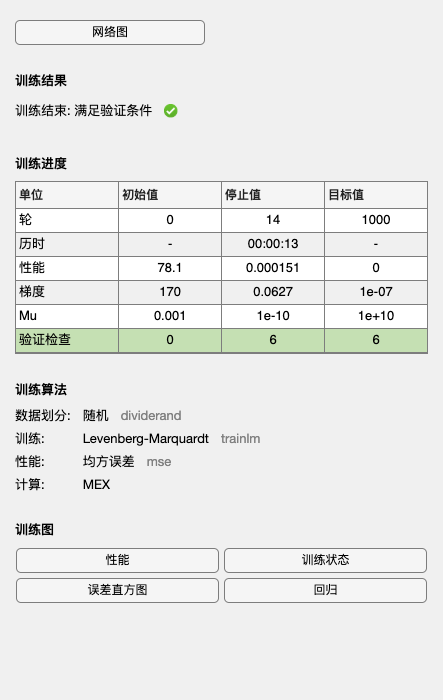

error = 1.2075

lag = 44;
neuron = 50;


for i=neuron:neuron
    [training, target_train] = getTimeSeriesTrainData(lasertrain_standardised, lag);
    % Formatting training data for train function
    train_set = cell(lag,1);
    
    for j=1:lag
        train_set{j,1} = training(j,:);
    end
    
    % Configuring and training the network

    net = feedforwardnet(i, 'trainlm');
    net.numInputs = lag;
    net.trainParam.epochs = 1000;
    for j=1:lag
        net.inputs{j}.size = 1;
        net.inputConnect(1,j) = 1;
    end

    [net,tr] = train(net, train_set, target_train);
    [test, target_predict] = getTimeSeriesTrainData(lasertest_standardised, lag);
    
    prediction = zeros(1,100-lag);
    x = test(:,1);
    
    for j=1:100-lag
        y = net(x);
        prediction(1, j) = y;
        x = vertcat(x(2:end),y);
    end
    error = sqrt(mean((prediction - target_predict).^2));error
end

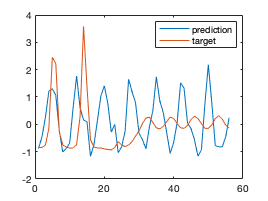


figure 
plot(prediction);
hold on;
plot(target_predict);
legend('prediction','target');
hold off;

x = all_lags;
y = all_neurons;
z = errors;
% % 
% create scatter plot in 3D space
scatter3(x, y, z);
% % 
% add labels and title
xlabel('Lags');
ylabel('Hidden_Units');
zlabel('RMSE');
title('RMSE on lags and hidden units');

x = all_lags;
y = all_neurons;
z = errors;


plot3(x, y, z)





% Plot lines based on the same x value in 3D space


% Add labels
xlabel('Lags')
ylabel('Hidden Units')
zlabel('RMSE')

% 找一个最小值，然后作图

x = all_lags;
y = all_neurons;
z = errors;

% Group the points based on the unique x-values
unique_x = unique(x);
num_groups = numel(unique_x);

% Set colors for each group
colors = lines(num_groups);

% Create a figure and hold on for multiple plots
figure
hold on

% Plot lines based on the same x-value using different colors
for i = 1:num_groups
    group_idx = (x == unique_x(i));
    plot3(x(group_idx), y(group_idx), z(group_idx), 'Color', colors(i, :))
end

% Add labels
xlabel('Lags')
ylabel('Hidden Units')
zlabel('RMSE')

% Release hold and adjust the view if needed
hold off
view(3)

